% Add path and load the data structure(vecLD)
addpath(genpath('../MLVcode'));
load('../dataSets/TorontoScenes/cities_vecLD.mat');

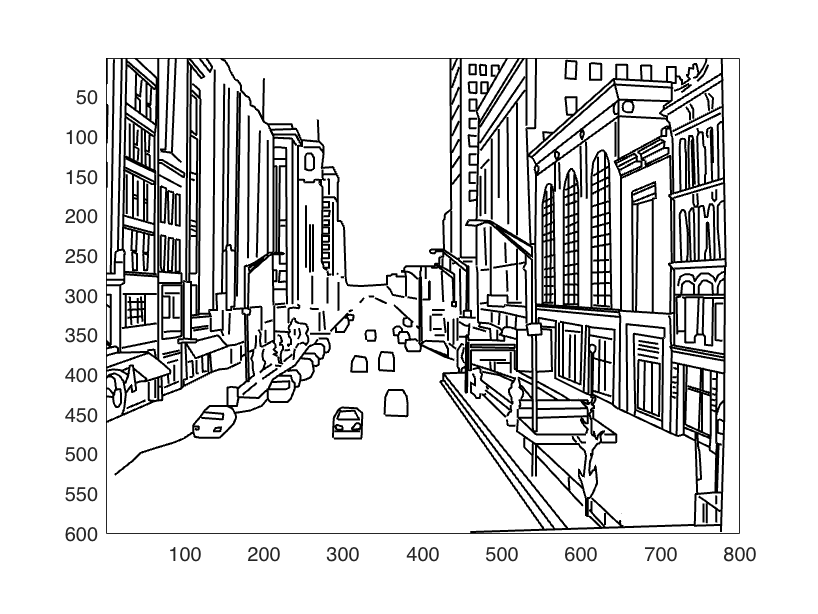

% Choose one image for demonstration 
% We use data structure 52 here (row 52) and call it 'cute'!
cute = vecLD(52);
% View 'cute' as a line drawing
figure;drawLinedrawing(cute);

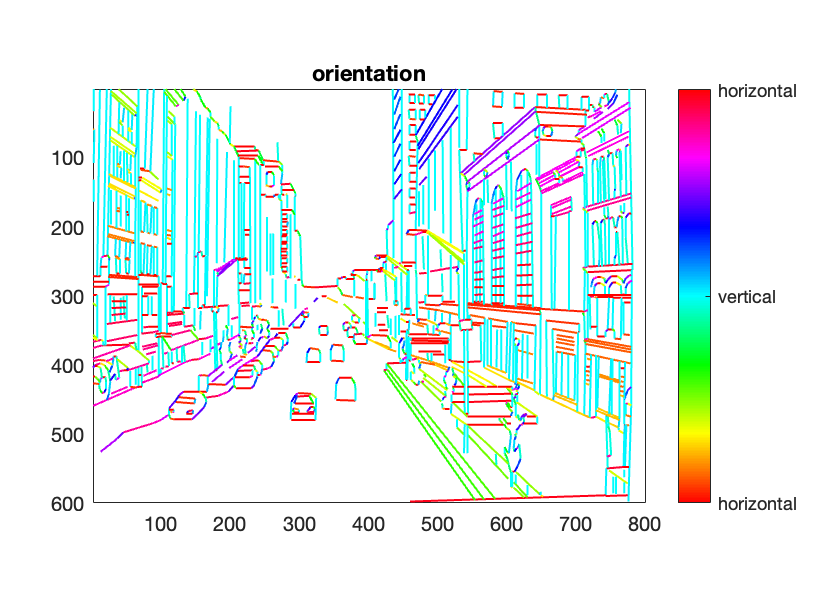

% Compute contour properties for 'cute' using the function
% We use the function computeContourProperties(vecLD,whichProps)
% You can specify which contour property to compute.
% default: {'orientation','length','curvature','junctions'}
cute = computeContourProperties(cute);

% Visualize contour orientation property for cute 
figure;drawLinedrawingProperty(cute,'orientation');
title('orientation');

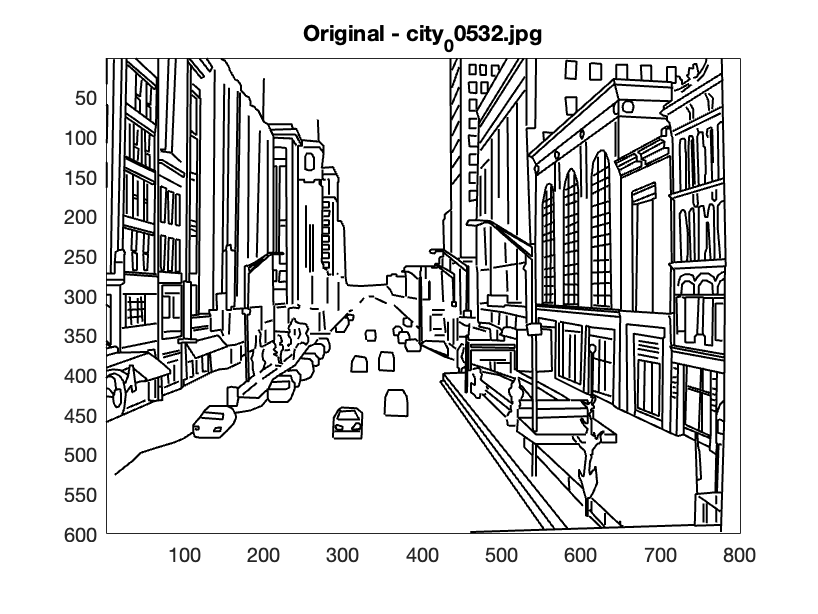

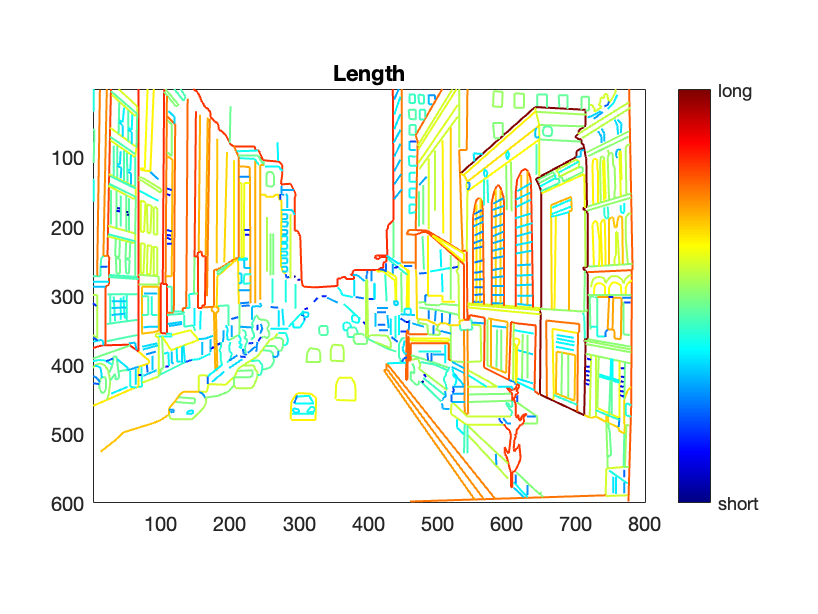

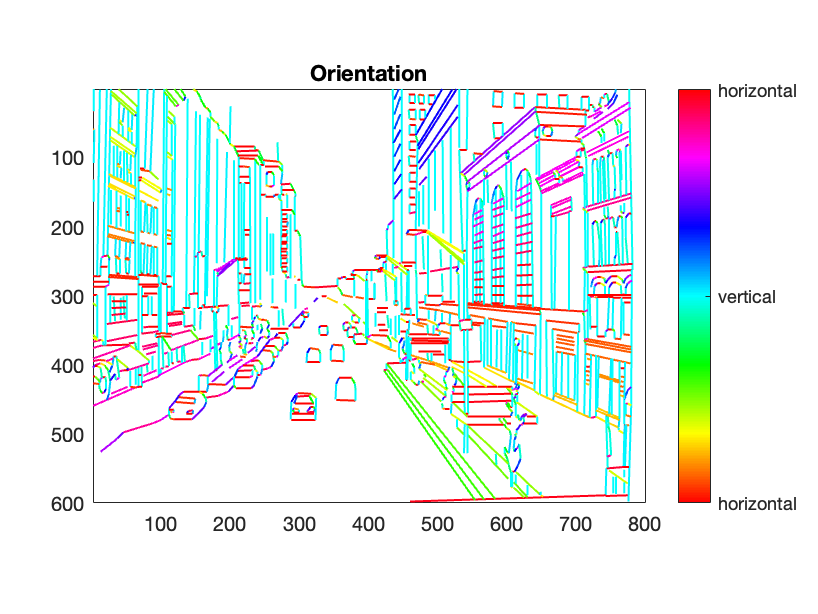

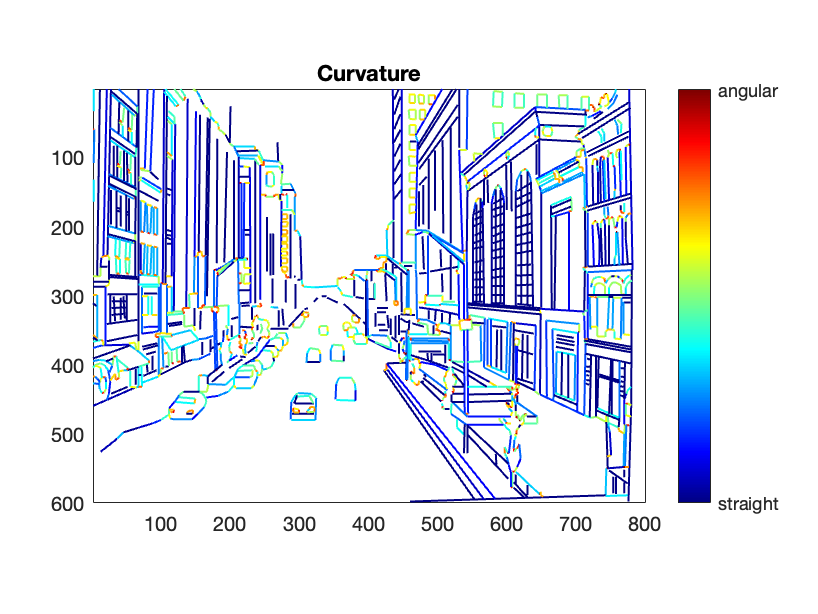


% draw all contour properties in separate plots
figure;drawAllProperties(cute, 'separate');

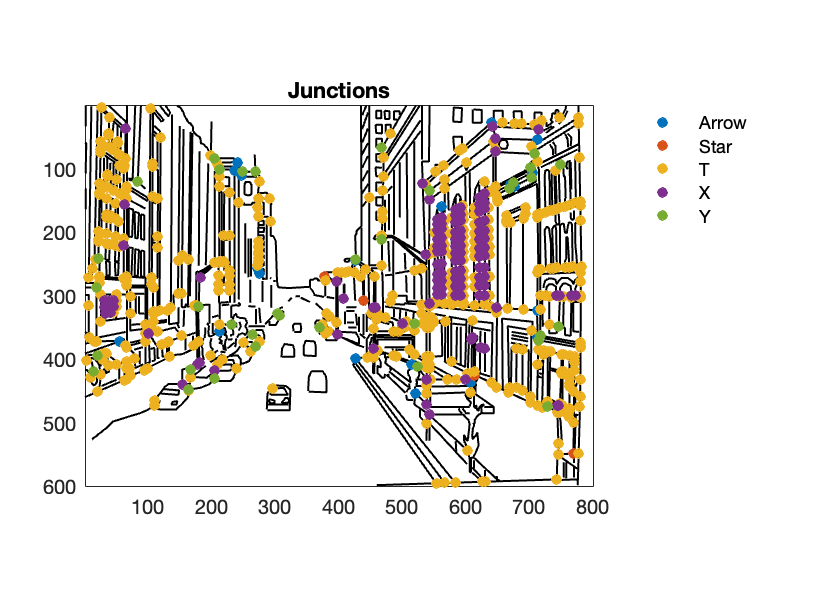

% save figures as a pdf file
saveas(gcf,'output/cutie.pdf')

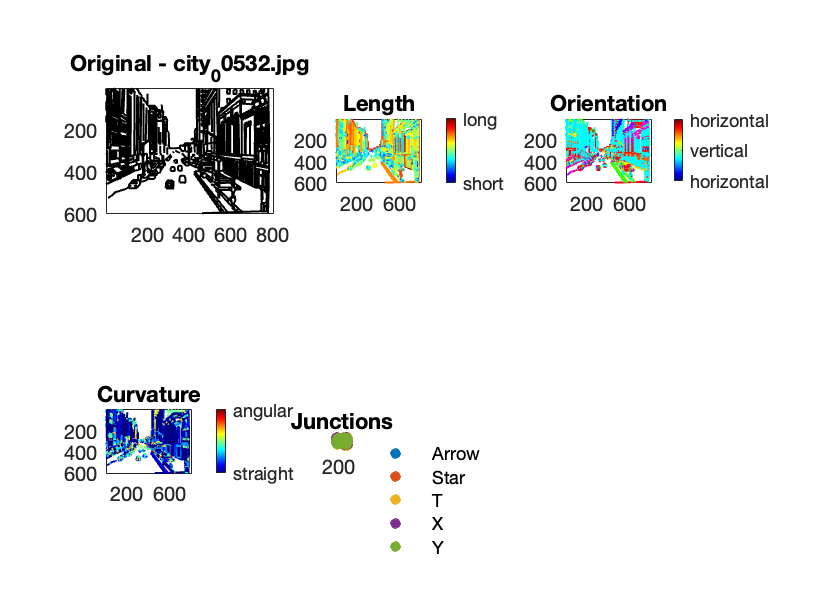

% Visualize all contour properties in one plot
drawAllProperties(cute);
% save figures as a jpg file
saveas(gcf,'output/cutie.jpg')

% Get contour properties statistics
% We use the function getContourPropertiesStats 
% [cute,histograms,bins,statsShortNames] = getContourPropertiesStats(cute, minmaxLen, minmaxCurv, whichStats)
% Input:
%   cute - vecLD data structure
%   whichStats - defines which properties to compute
%                default: {'orientation','length','curvature','junctions'}
%   minmaxLen - this minimum and maximum for the length histogram 
%               (default: [2, width+length of the image])
%   minmaxCurv- this minimum and maximum for the curvature histogram 
%               default: [0, 90]
%   junctionTypes - a cell array with the junction types to incldue in the histogram
%                   default: {} - use all junction types present in this
%                   image
%
% Output:
%   cute -       vecLD with the individual contour stats added
%   histograms - cell array of histograms for the features 
%                in the same order as in whichstats
%   bins -       cell array of bin centers for those histograms
%                in the same order as in whichstats
%   statsNames - the order of stats in the histgrams and bins
[cute,histograms,bins,statsNames] = getContourPropertiesStats(cute);

% Convert histograms into table
imageFeatures = {'normSumLengthHistogram','normSumOrientationHistogram','normSumCurvatureHistogram','normJunctionTypeHistogram'};
cute_contourStats = allLDHistogramsToTable(cute,imageFeatures,statsNames)

cute_contourStats = 1×29 table
    ori_1     ori_2     ori_3     ori_4     ori_5    ori_6     ori_7     ori_8     len_1     len_2     len_3    len_4     len_5     len_6     len_7     len_8     curv_1    curv_2    curv_3    curv_4    curv_5    curv_6    curv_7    curv_8    juncType_T    juncType_Y    juncType_X    juncType_Arrow    juncType_Star
    ______    ______    ______    ______    _____    ______



% Export table to csv
writetable(cute_contourStats,'Output/cute_contourStats.csv');

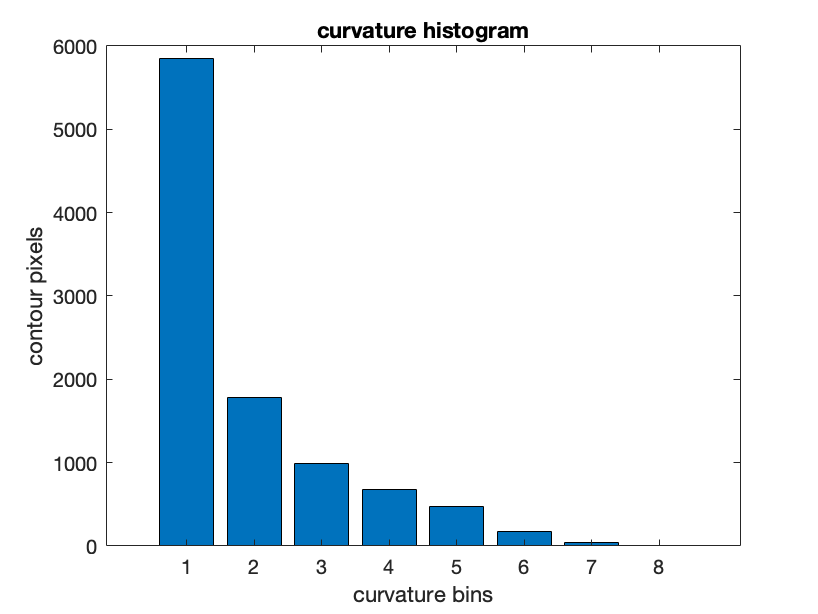

% Bar graph of histograms for different contour statistics 
figure;
bar(cute.normSumCurvatureHistogram);
title('curvature histogram');
xlabel('curvature bins')
ylabel('contour pixels');

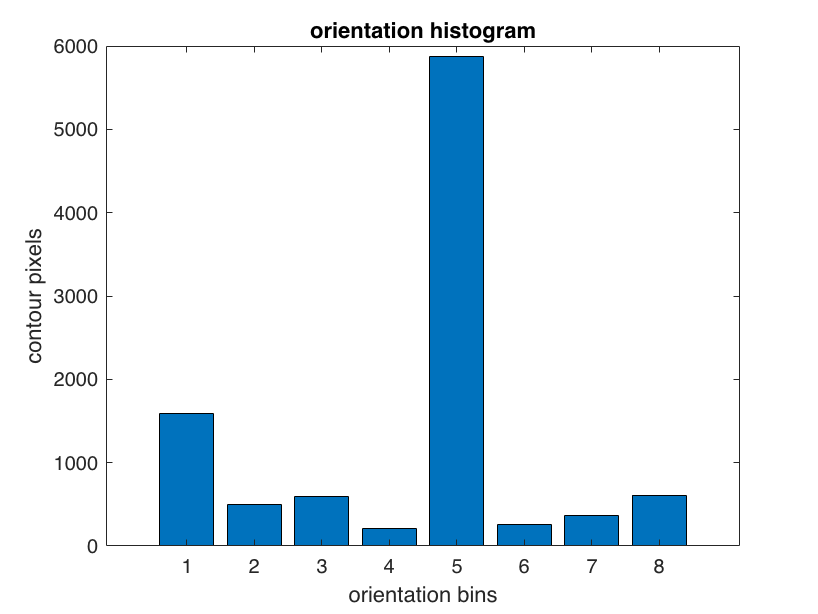


figure;
bar(cute.normSumOrientationHistogram);
title('orientation histogram');
xlabel('orientation bins')
ylabel('contour pixels');

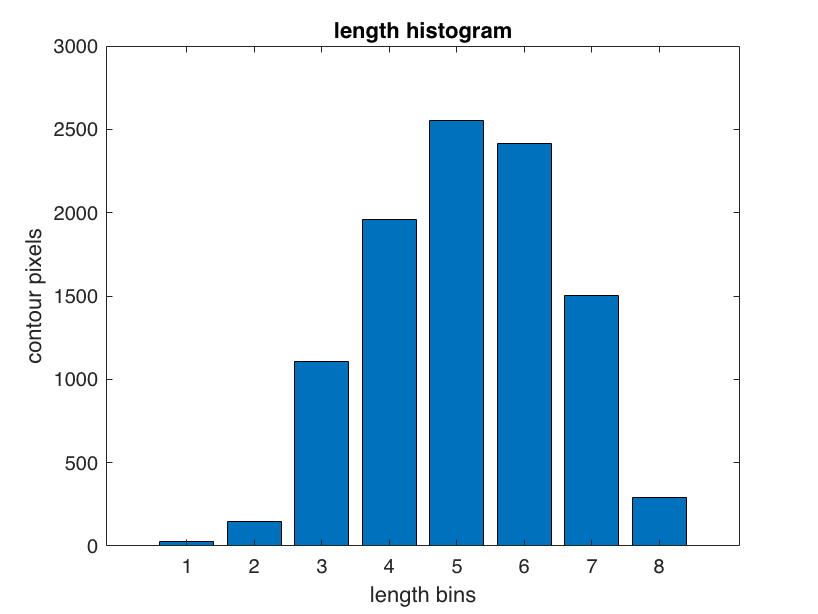


figure;
bar(cute.normSumLengthHistogram);
title('length histogram');
xlabel('length bins')
ylabel('contour pixels');

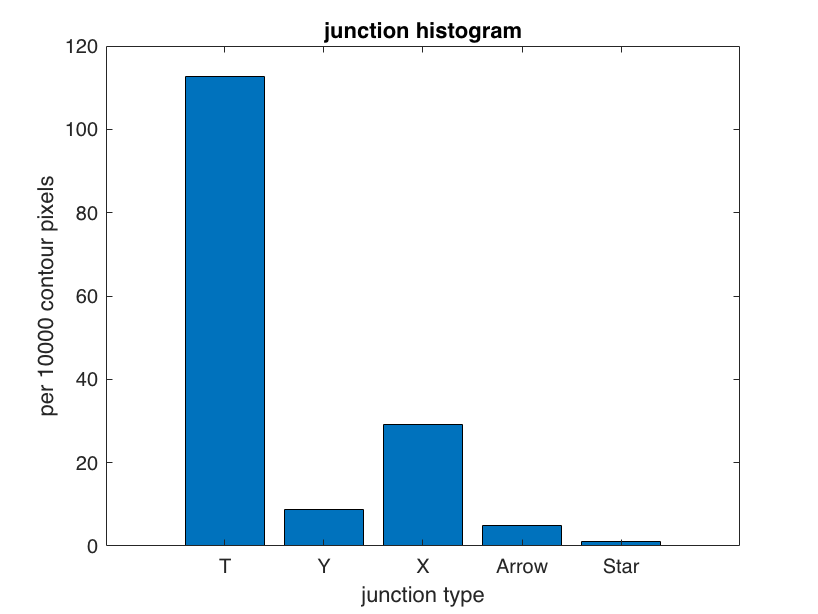


figure;
bar(cute.normJunctionTypeHistogram);
title('junction histogram');
xlabel('junction type');
xticklabels(cute.junctionTypeBins);
ylabel('per 10000 contour pixels');

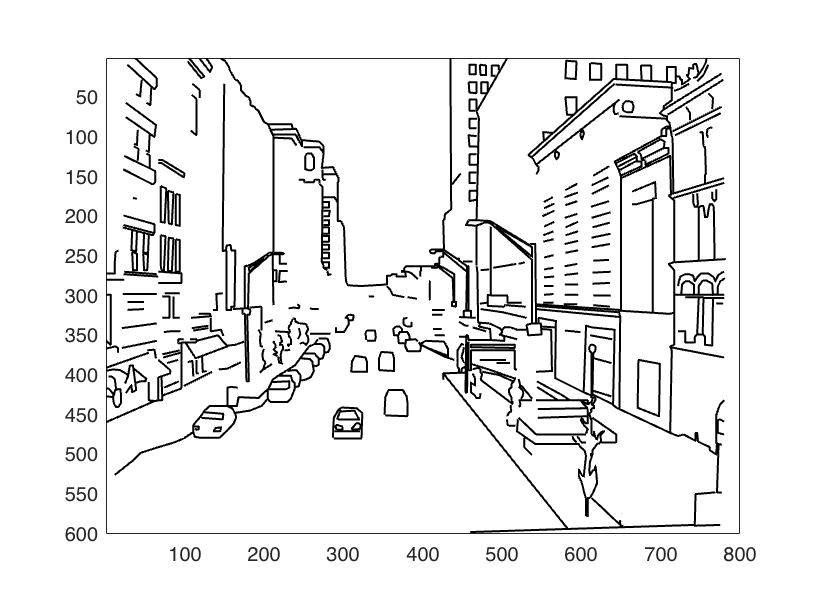

% Example of image manipulations
% We will use the function splitLDbyProperties
% Make manipulated versions of a line drawing with varying amounts of
% given contour properties (e.g. top image is a version with 50% of pixels with highest
% curvature stats)
% In this example, we are generating top and bottom splits for 'cute' based on
% curvature and orientation of contours in 50% of pixels (specified as 0.5 in the
% third argument of the function)
[top,bottom] = splitLDbyProperties(cute,{'curvature', 'orientation'},0.5,[1,1]);
% Next, we draw manipulated line drawings into figures. 
figure;
drawLinedrawing(top);

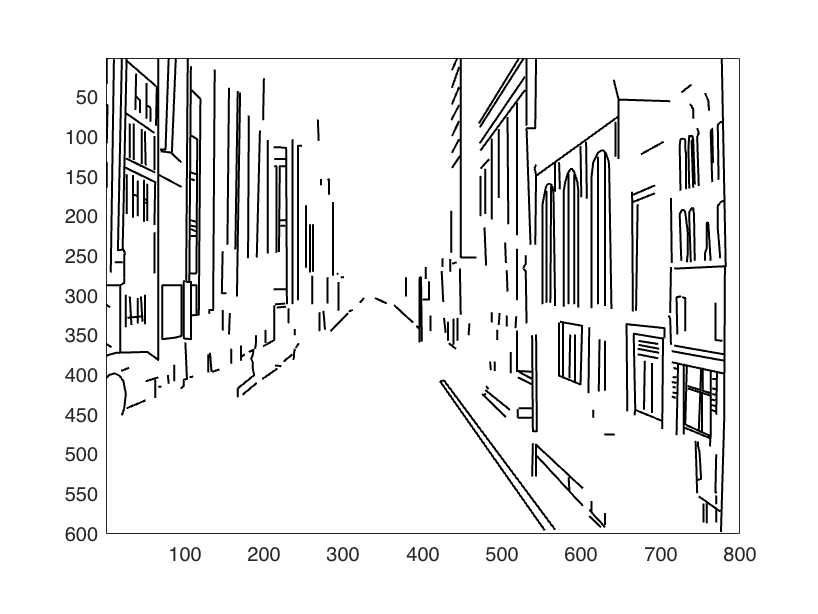

figure;
drawLinedrawing(bottom);

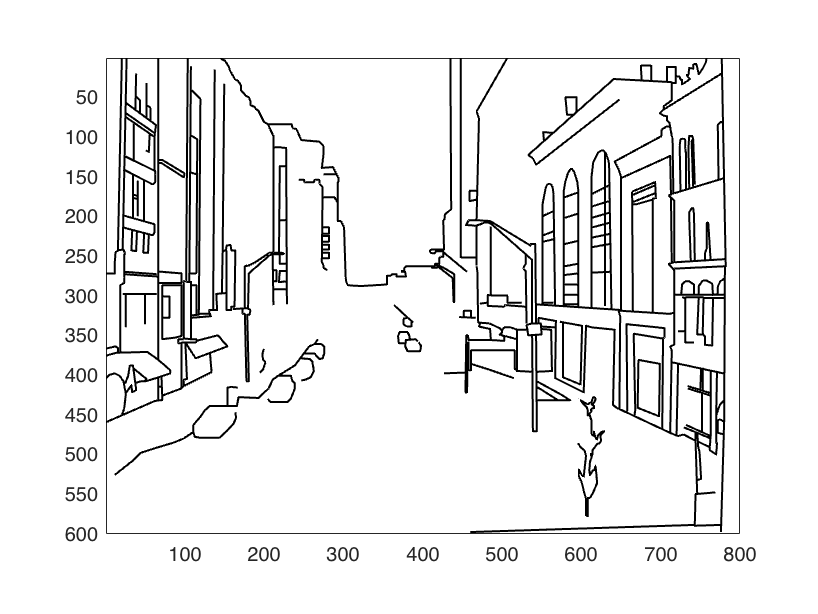

% Split image into two versions based on histogram weights for T junctions 
% We will use the splitLDbyHistogramWeights function
% Weights argument in the splitLDbyProperties is used to select junction
% Junction type is specified according to the following order in the last argument: T,Y,X,Arrow,Star
% For example, to specify X junctions, we set the last argument to
% {[0,0,1,0,0]
[top2,bottom2] = splitLDbyHistogramWeights(cute,'junctions',0.5,{[1,0,0,0,0]}); 
figure;
drawLinedrawing(top2);

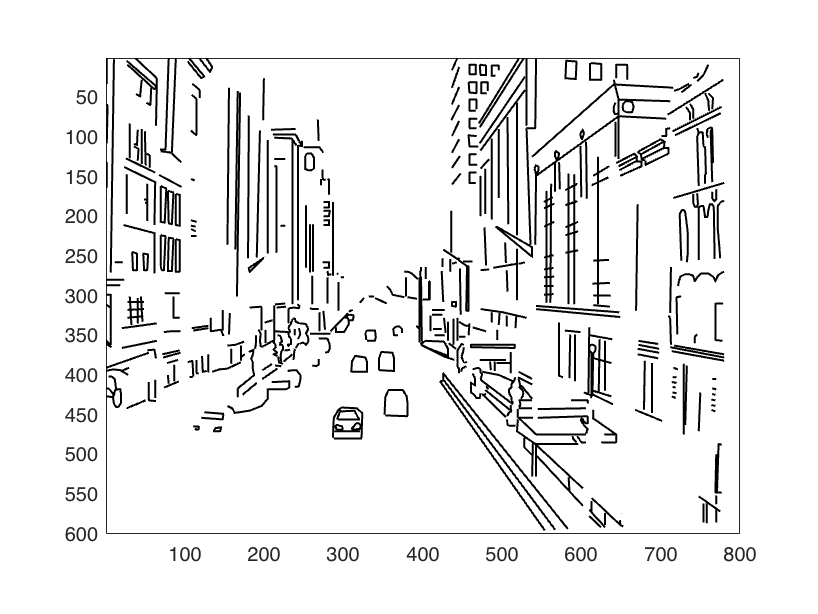

figure;
drawLinedrawing(bottom2);

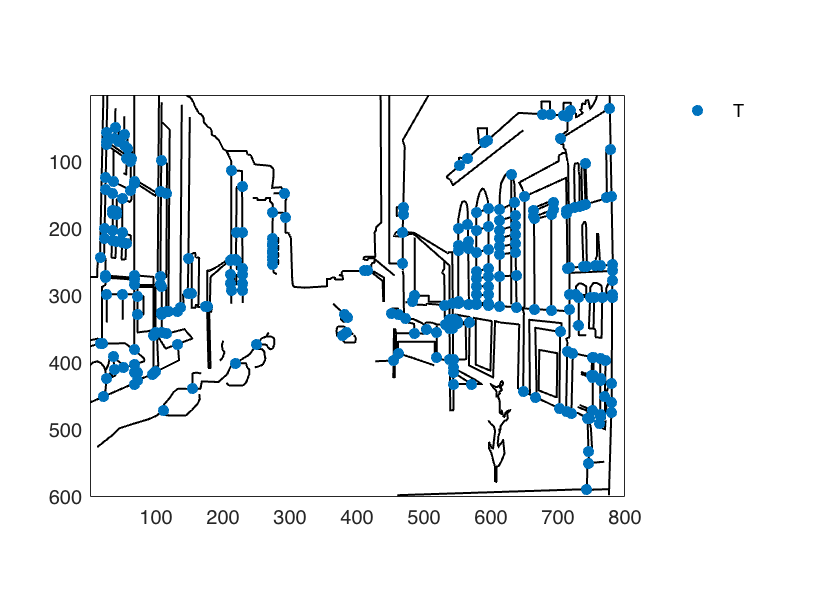


% Visualize T junctions overlayed on top half-split drawing version
figure;
drawLinedrawing(top2);
drawJunctions(top2.junctions,{'T'});

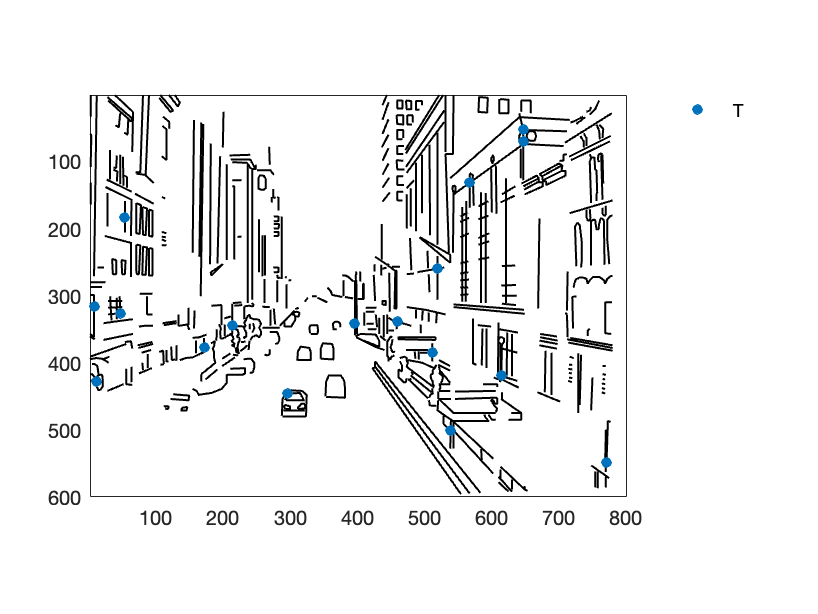


% Visualize T junctions overlayed on bottom half-split drawing version
figure;
drawLinedrawing(bottom2);
drawJunctions(bottom2.junctions,{'T'});

% Export split versions of images to output folder
cuteTop = renderLinedrawing(top,[],[],3);

'insertShape' requires Computer Vision Toolbox.

Error in renderLinedrawing (line 60)
    img = insertShape(img,'Line',scaledCoords,'Color',color,'LineWidth',lineWidth,'SmoothEdges',false);

imshow(cuteTop)
imwrite(cuteTop,'Output/cuteTop.png')

cuteBottom = renderLinedrawing(bottom,[],[],3);
imshow(cuteBottom)
imwrite(cuteBottom,'Output/cuteBottom.png')
